# Max Lyapunov Exponent

Here we apply max Lyapunov exponent approach using the algorithm suggested by Rosenstein, 1993 with the modification suggested by Beaudette, 2016 to two different examples:

- Calculating max Lyapunov exponent for recorded kinematic data of a repetitive handling task.

- Lorenz system.

**Refs:**

- Rosenstein, Michael T., James J. Collins, and Carlo J. De Luca. "A practical method for calculating largest Lyapunov exponents from small data sets." *Physica D: Nonlinear Phenomena* 65.1-2 (1993): 117-134.

- Beaudette, Shawn M., et al. "On the use of a Euclidean norm function for the estimation of local dynamic stability from 3D kinematics using time-delayed Lyapunov analyses." *Medical engineering & physics* 38.10 (2016): 1139-1145.

**Prerequisits:**

- Statistics and Machine Learning Toolbox (***pdist*** function)

## Preparation

clear all; clc;
startup_project;
mdc = material_design_colors;

## Repetitive lifting task

Trunk rotation was extracted from the T8 segment. As the number of data samples per cycle can influence the estimate of stability, the data were resampled to obtain a mean value of 300 data samples per movement cycle (50 samples per second) while preserving the cycle-to-cycle variability in movement. The Euclidean norm transformation function was used to combine the rotation into a single time-series. Prior to normalization, T8 rotations were independently shifted to avoid the incidence of zero-crossings (Beaudette et al., 2016). In order to reconstruct the state-space of the normalized signal, a constant time delay of 30 samples (10% of the length of the average cycle) with embedding dimension of 5 was used for all trials (Granata and England, 2006).

**Ref: **Granata, Kevin P., and Scott A. England. "Stability of dynamic trunk movement." *Spine* 31.10 (2006)

### Loading data

data = load("inp\sample_data.mat").data;

Creating timeseries signal

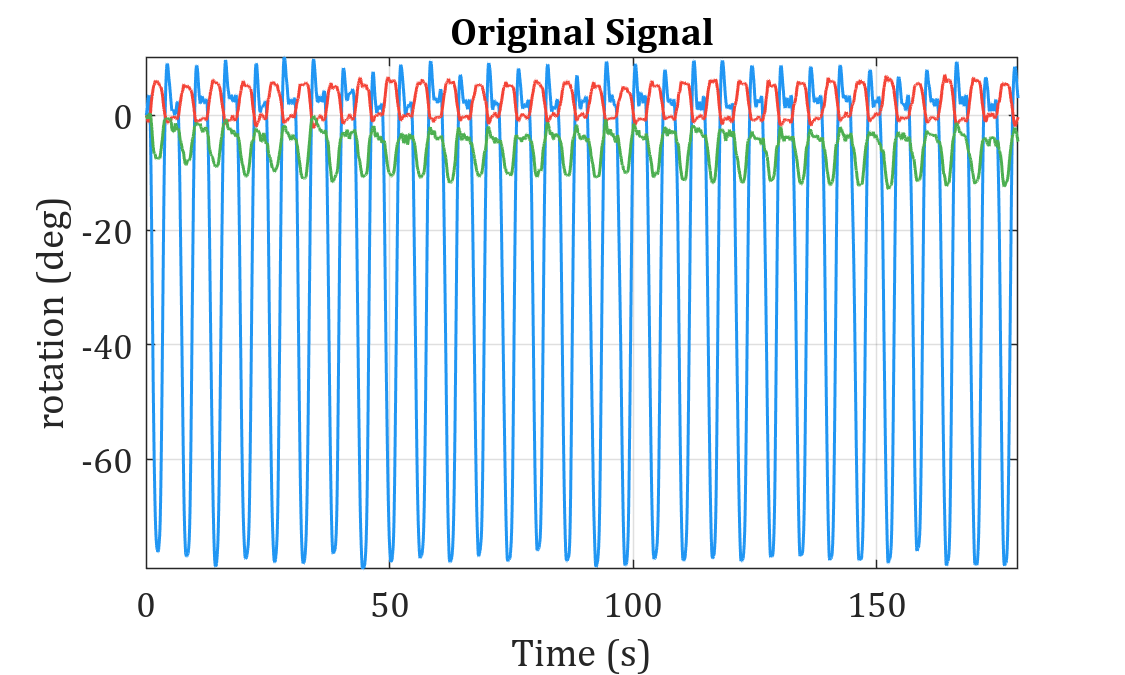

sigOrg = timeseries(data.rotThorax, data.time);

fig = figure("Position", [10, 10, 500, 300]); axs = axes(fig);
plot(axs, sigOrg.Time, sigOrg.Data, 'LineWidth', 1);
axis(axs, 'tight'); xlabel(axs, "Time (s)"); ylabel(axs, "rotation (deg)");
title(axs, "Original Signal")
print(fig,'README-figs\spine-org-sig.jpg', '-dpng', '-r200');

#### Normalizing using Beaudette et al. 2016

Based on Beaudette, 2016, to develop a standard for the analysis of 3D dynamic kinematic waveforms, all dimensions of a 3D signal should be shifted  independently to avoid the incidence of zero-crossings prior to the calculation of Euclidean norm and subsequent estimation of local dynamic stability through the use of  .

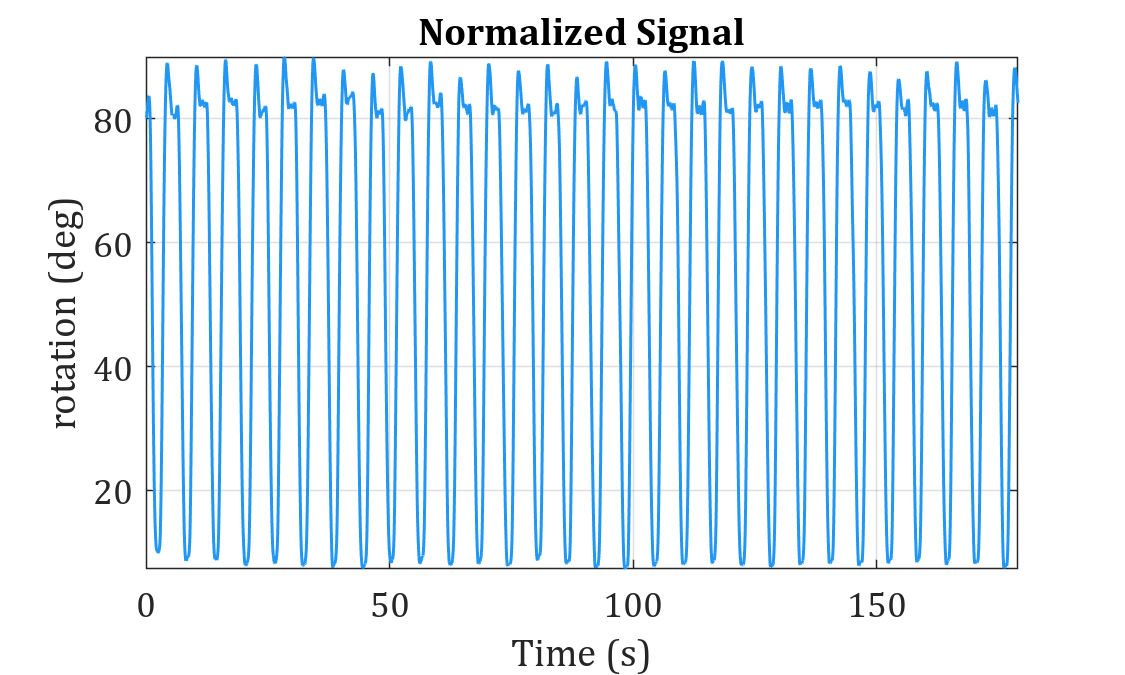

sig = Lyapunov_Exponent.normalize_Beaudette_2016(sigOrg);

fig = figure("Position", [10, 10, 500, 300]); axs = axes(fig);
plot(axs, sig.Time, sig.Data, 'LineWidth', 1);
axis(axs, 'tight'); xlabel(axs, "Time (s)"); ylabel(axs, "rotation (deg)");
title(axs, "Normalized Signal")
print(fig,'README-figs\spine-org-sig-norm.jpg', '-dpng', '-r200');

#### Calculating Lyapunov Exponent

Short-term and long-term LyE (LyE-S, LyE-L) were identified by fitting a line through the average logarithmic divergence plot spanning over 0–0.5 and 4–10 cycles, respectively [(Beaudette et al., 2016; Madinei et al., 2021)](https://www.zotero.org/google-docs/?oUs7Bk). Larger exponents indicate greater sensitivity to local perturbations, with negative and positive signs corresponding to local stability and local instability, respectively.

dt = 0.02;
objLyExp = Lyapunov_Exponent(sig);
objLyExp.embedingDimension = 5;
objLyExp.reconstructionDelay = 0.6;
objLyExp.meanPeriod = 0.6;
objLyExp.maxTime = 60;
objLyExp.rangeShortLyE = [dt 3];
objLyExp.rangeLongLyE = [24 60];
objLyExp.prepare_for_lyapunov;
objLyExp.calc_divergence([]);
objLyExp.calc_lyapunov_exponent;

### Ploting reconstructed trajectory

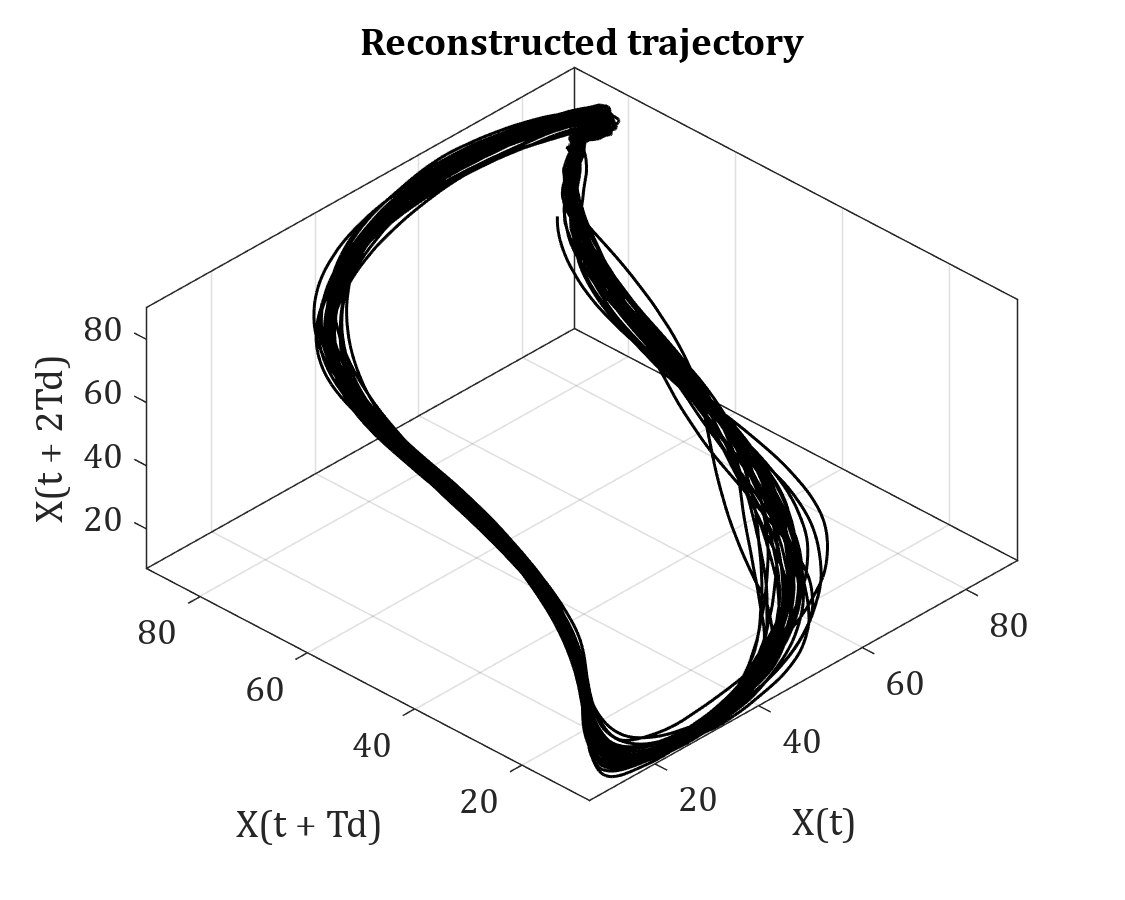

fig = figure("Position", [10, 10, 500, 400]); axs = axes(fig);
objLyExp.plot_reconstructed_trajectory(axs);
view(axs, [-46 52]);
print(fig,'README-figs\spine-sig-reconstructed.jpg', '-dpng', '-r200');

### Ploting divergence curve

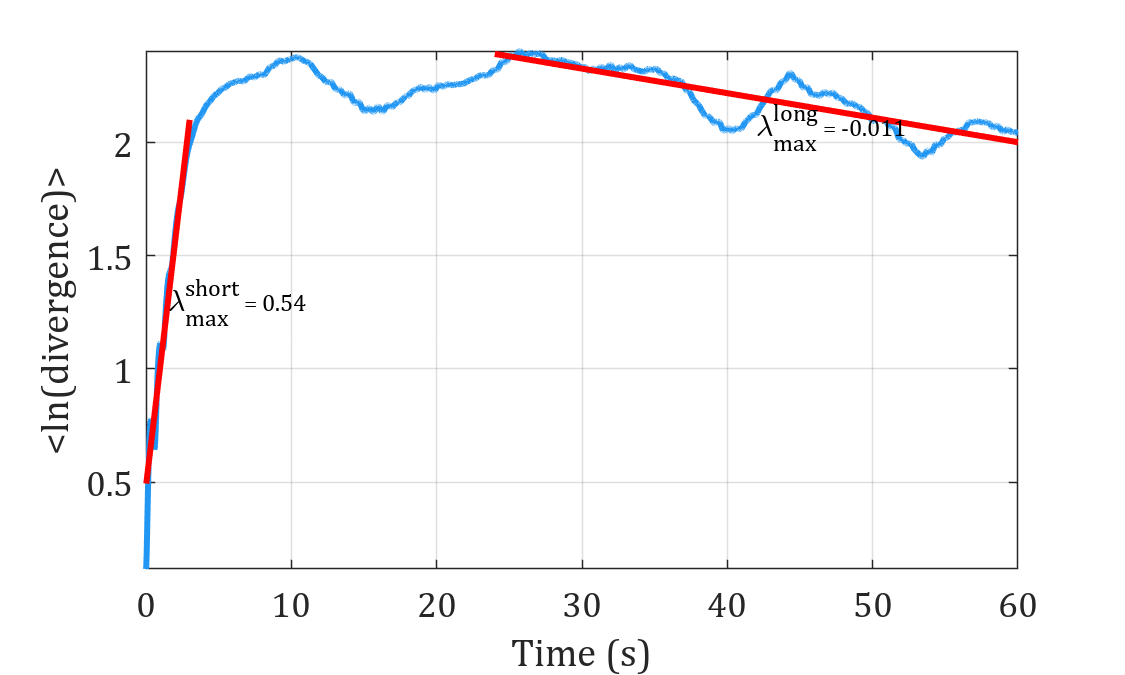

fig = figure("Position", [10, 10, 500, 300]); axs = axes(fig);
objLyExp.plot_divergence_curve(axs);
print(fig,'README-figs\spine-convergence.jpg', '-dpng', '-r200');

## Lorenz system

### Data generation

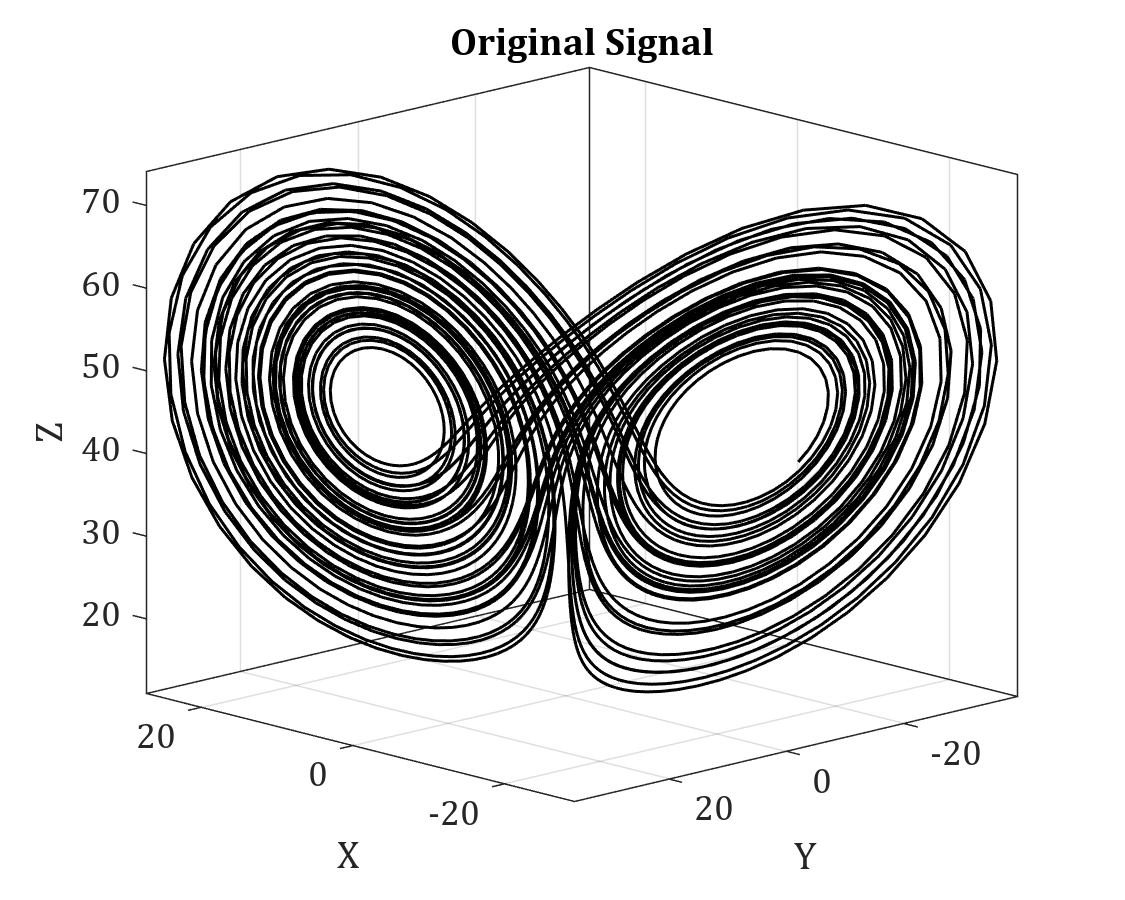

totalTime = 40; dt = 0.01;
sigOrg = Lyapunov_Exponent.sample_lorenz(totalTime, dt);
sigOrg.Name = "Lorenz system";

fig = figure("Position", [10, 10, 500, 400]); axs = axes(fig);
plot3(axs, sigOrg.Data(:,1), sigOrg.Data(:,2), sigOrg.Data(:,3), 'k-', 'LineWidth', 1);
view(axs, [-134, 16]); axis(axs, 'tight');
xlabel(axs, "X"); ylabel(axs, "Y"); zlabel(axs, "Z");
title(axs, "Original Signal");
print(fig,'README-figs\lorenz-org-sig.jpg', '-dpng', '-r200');

### Calculating max Lyapunov exponent based on a single state

Taking the first state of the original signal.

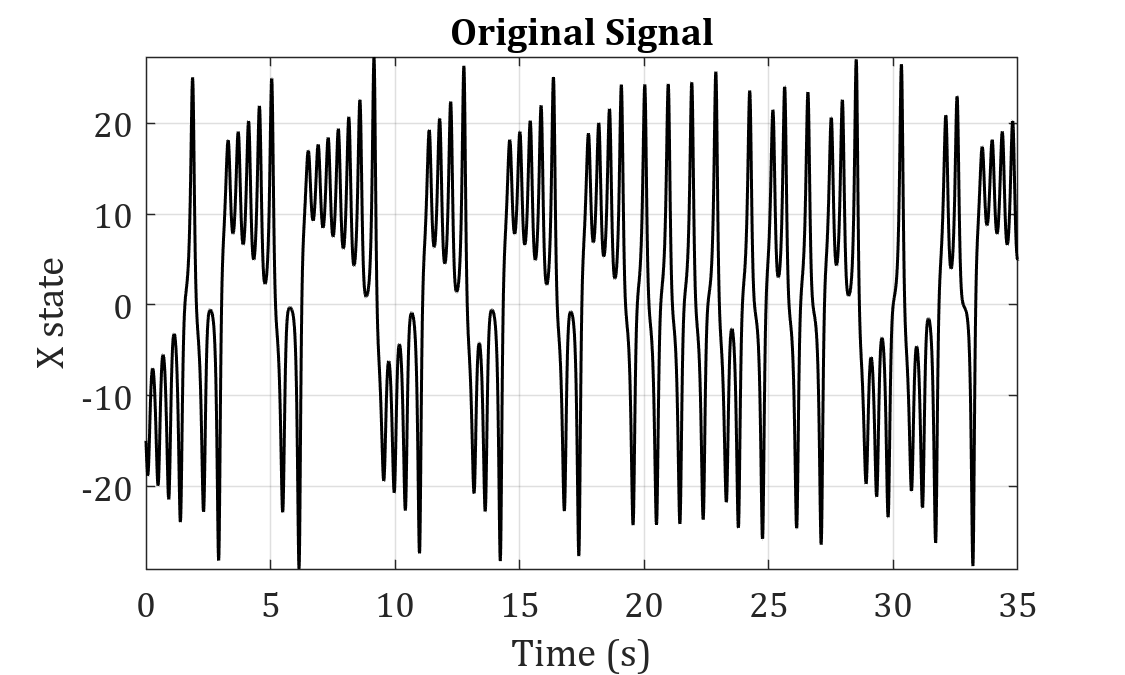

sig = sigOrg; sig.Data(:, [2,3]) = [];

fig = figure("Position", [10, 10, 500, 300]); axs = axes(fig);
plot(axs, sig.Time, sig.Data(:,1), 'k-', 'LineWidth', 1);
axis(axs, 'tight');
xlabel(axs, "Time (s)"); ylabel(axs, "X state");
title(axs, "Original Signal");
print(fig,'README-figs\lorenz-org-sig-x.jpg', '-dpng', '-r200');

### Building Lyapunov exponent object

objLyExp = Lyapunov_Exponent(sig);
objLyExp.embedingDimension = 3;
objLyExp.reconstructionDelay = 11*dt;
objLyExp.meanPeriod = 20*dt;
objLyExp.maxTime = 300*dt;
objLyExp.rangeShortLyE = [0, 2];
objLyExp.prepare_for_lyapunov;
objLyExp.calc_divergence([]);
objLyExp.calc_lyapunov_exponent;

### Ploting reconstructed trajectory

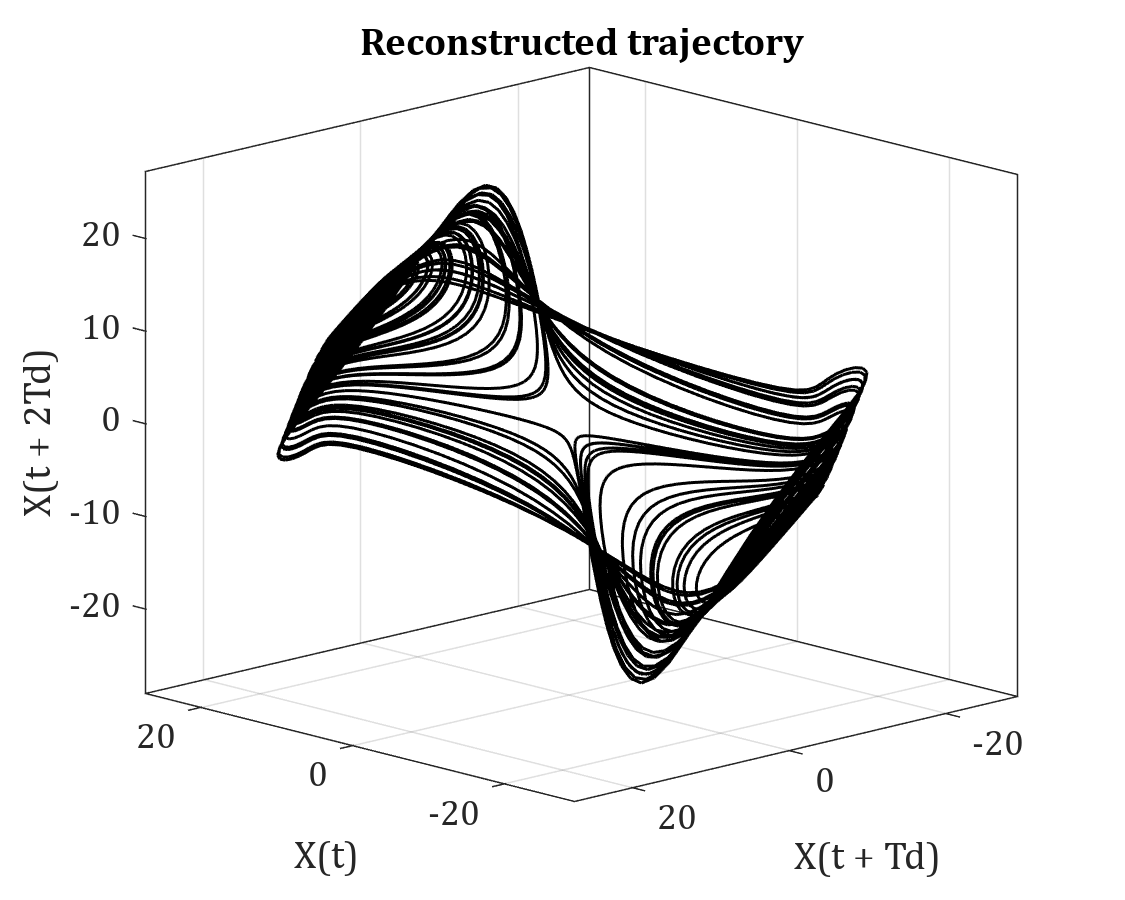

fig = figure("Position", [10, 10, 500, 400]); axs = axes(fig);
objLyExp.plot_reconstructed_trajectory(axs);
view(axs, [-134, 16]);
print(fig,'README-figs\lorenz-reconstructed.jpg', '-dpng', '-r200');

### Ploting divergence curve

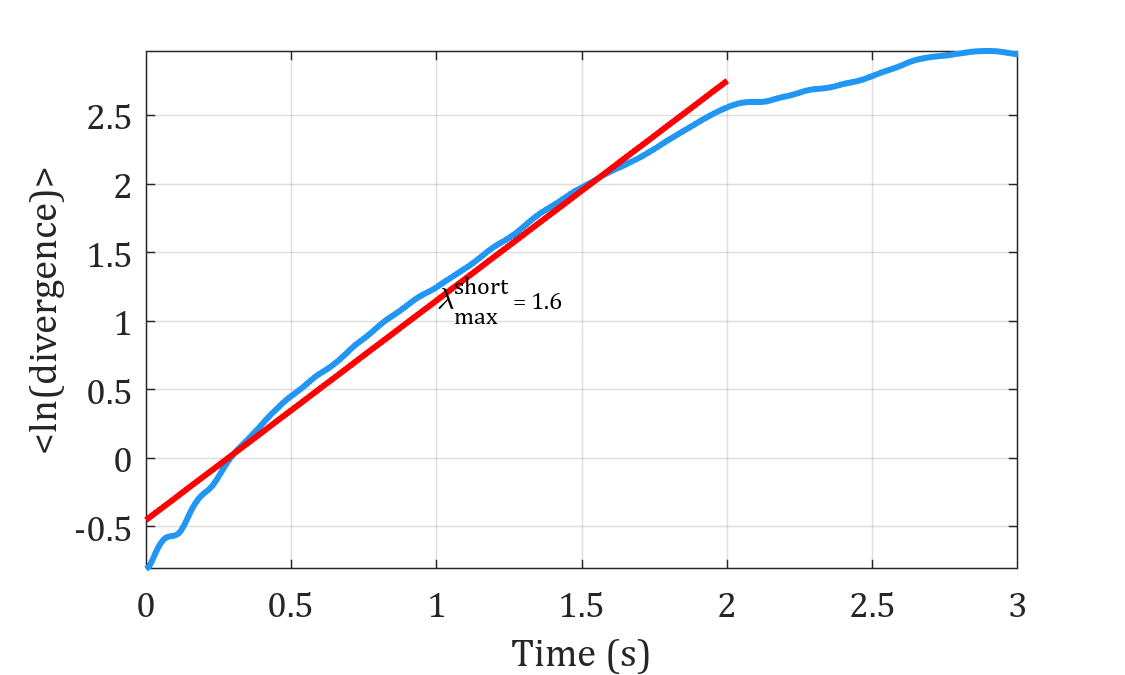

fig = figure("Position", [10, 10, 500, 300]); axs = axes(fig);
objLyExp.plot_divergence_curve(axs);
print(fig,'README-figs\lorenz-convergence.jpg', '-dpng', '-r200');